## **Initialization**

clc;
clear;
img_org = imread("charact2.bmp");%read the original image

## 1.Display the original image

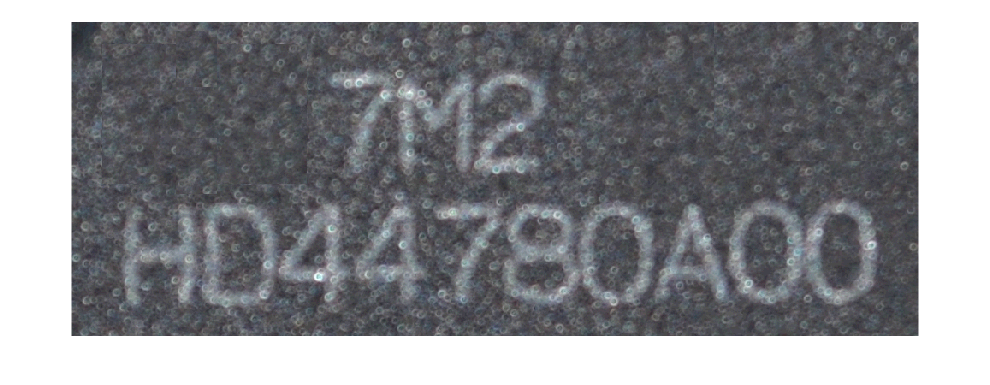

figure("Name","the original image");
imshow(img_org);

img_gray = rgb2gray(img_org);% transform to gray image

## 2.Implement 3x3 averaging mask and rotating mask.Try masks in other sizes

### 2.1 Apply 3x3 averaging mask on the original image

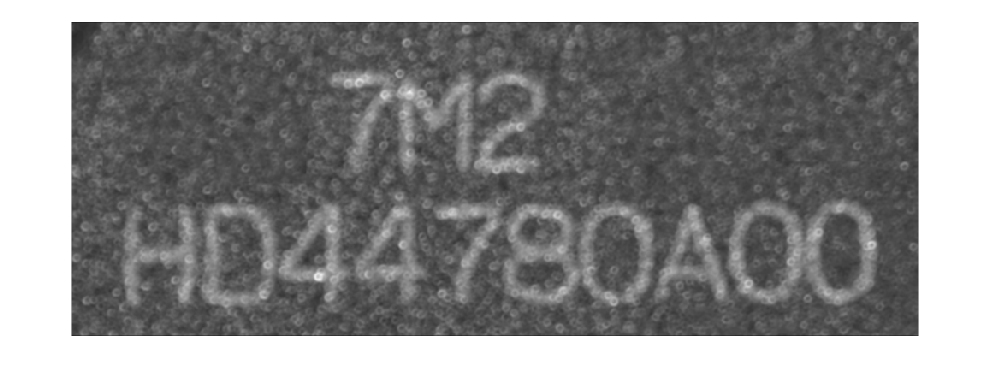

figure("Name","3x3 averaging mask image");
average_mask_3by3 = ones(3,3)./9;                       % create the mask
img_3by3average = imfilter(img_gray,average_mask_3by3);  % apply the mask
imshow(img_3by3average);                                % display the 3x3 averaged image

%There are not many differents.This one is a bit darker and blurry

### 2.2 Apply 3x3 rotating mask on the original image

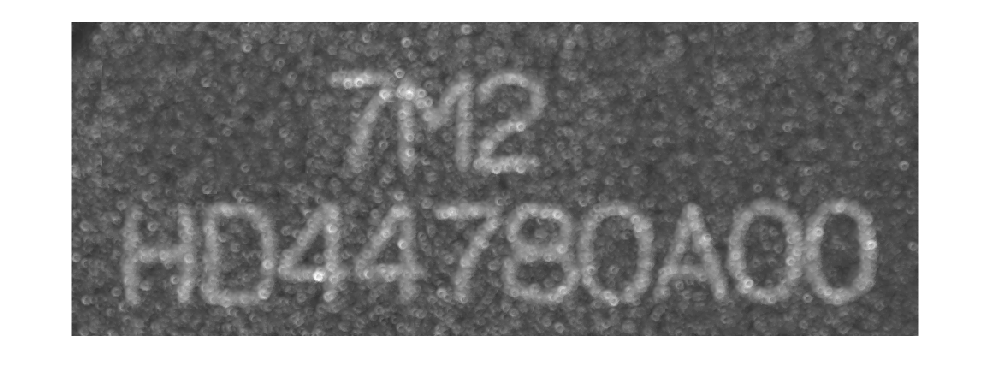

figure("Name","3x3 rotate averaging mask image");
img_3by3rotate = img_gray;%initialize 3x3 rotating masked image
for i = 3:365
    for j = 3:988
        dispersion = 0;
        dispersion_min = 0;
        for k = -1:1
            for l = -1:1
                %calculate dispersion
                dispersion = 1 / 9 * (img_gray(i,j) - mean(mean(img_gray(i+k-1:i+k+1,j+l-1:j+l+1)))) ^ 2;
                if dispersion <= dispersion_min
                    dispersion_min = dispersion;
                    img_3by3rotate(i,j) = mean(mean(img_gray(i+k-1:i+k+1,j+l-1:j+l+1)));
                end
            end
        end
    end
end
imshow(img_3by3rotate);

%There are not many differents.This one is a bit clearer and has higher contrast.

### 2.3 Test other mask

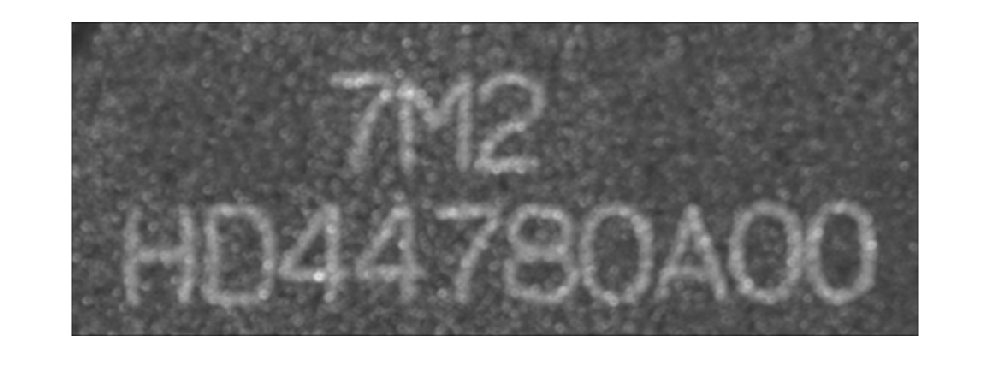

figure("Name","5x5 averaging mask image");
average_mask_5by5 = ones(5,5)./25;                       % create the mask
img_5by5average = imfilter(img_gray,average_mask_5by5);  % apply the mask
imshow(img_5by5average);                                % display the 5x5 averaged image

%This one is even more blurry due to bigger average range

## 3. Create an image which is a sub-image of the original image comprising the middle  line – HD44780A00.

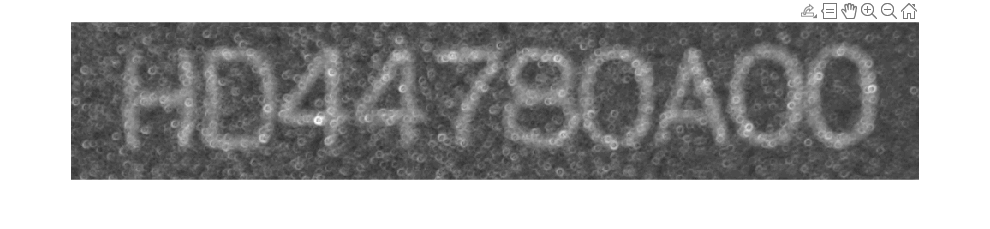

figure("Name","Cropped sub image - HD4478A00");
img_hd = imcrop(img_gray,[1 184 990 367]); %Crop a sub-image
imshow(img_hd);

## 4. Create a binary image from Step 3 using thresholding.

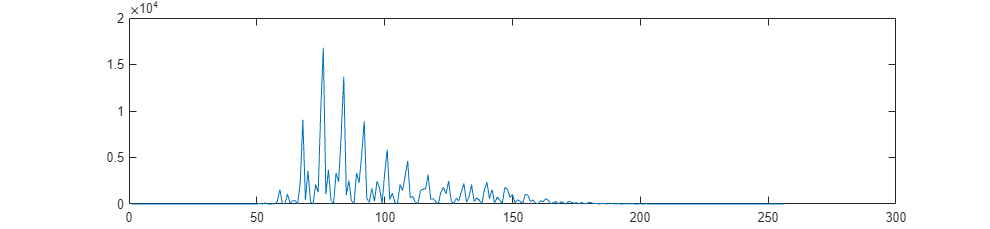

% create a gray level histogram first
plot(imhist(img_hd)); %105seems to be a good threshold value

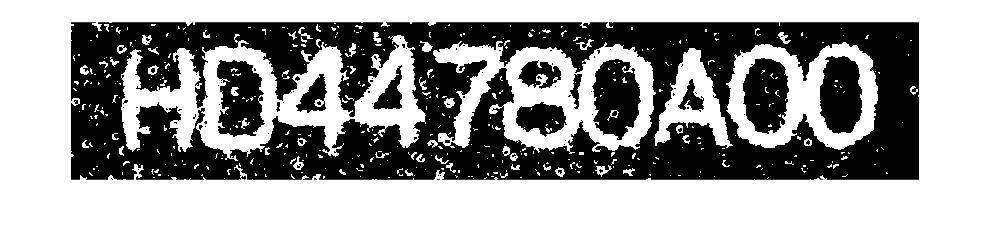

% thresgold the image
img_threshold = imbinarize(img_hd,105/255); %apply thresholding
imshow(img_threshold); %show image

##  5. Determine the outline(s) of characters in the image.

%% Implement segmentation




